# RADAR DE ABERTURA SINTÉTICA - ET291

## Relatório sobre trabalho de Algoritmo Retangular (Range Azimuth Algorithm)

### Carlos Vinícius de Souza Augusto

clear all;
close all;
clc;

## *1º Passo*: Definir os parâmetros do sensor ERS-1 que foi disponibilizado em aula

prf = 1679.902; % Repetição do Pulso
fs = 18.9624680e6; % [Hz] Frequência de Amostragem
lambda = 0.056660; % [m]
tau = 37.12e-6; % [s] Duração do  Chirp
lant = 12; % [m] Comprimento da Abertura da Antena
fre_chirp = 1.55083e7; % [m/s]
vel = 7120.7327; % [m/s]
fdc = 490.51826; %[Hz] Frequencia Doppler Centroide
ran_ini = 850931; % [m] Distancia da Primeira Amostra
ts = 1/fs; % Tempo de Amostragem
N = 2048; % Tamanho da Imagem Raw

## *2º Passo: *Importar os arquivos .txt dos dados Reais e Imaginários da imagem Raw e tranformá-los em uma matriz

fid_raw_real = fopen('raw_data_ers1_real.txt','r');
fid_raw_imag = fopen('raw_data_ers1_imag.txt','r');

%transformar arquivos real e imag em um array
raw_real = textscan(fid_raw_real,'%n');
raw_real = raw_real{1};

raw_imag = textscan(fid_raw_imag,'%n');
raw_imag = raw_imag{1};

## *3º Passo*: Gerar a imagem Raw

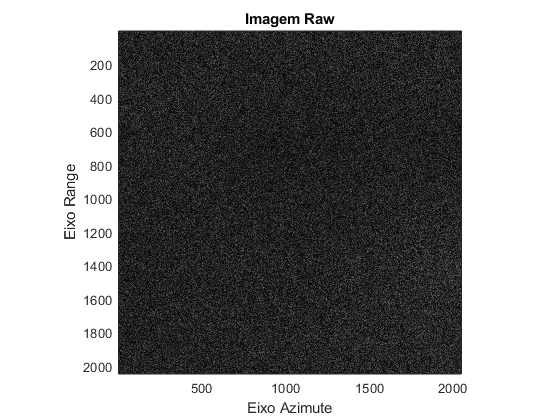

raw_data = complex(raw_real,raw_imag); % criada uma matriz complexa com os dados real e imag

raw_data = reshape(raw_data,N,[]); % convertido para o tamanho original da imagem 2048x2048

%Plots
figure
imagesc(abs(raw_data), [0 50]);
axis image
colormap('gray');
title ('Imagem Raw')
xlabel('Eixo Azimute')
ylabel('Eixo Range')

## *4º Passo:* Geração do sinal em Range

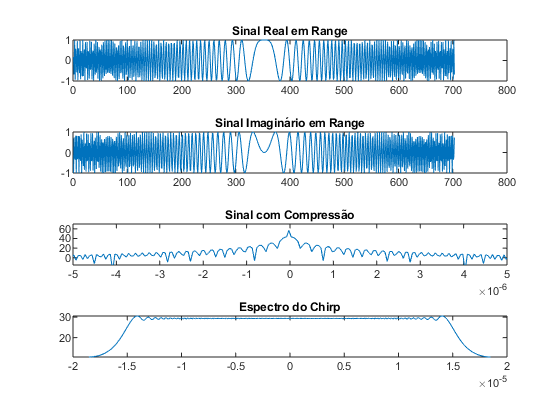

K = fre_chirp/tau; % Taxa de modulação do sinal FM

npts = floor(tau*fs);

t = [-npts/2:npts/2-1]'*ts; %Eixo do tempo

signal_chirp = exp(j*pi*K*t.^2); %Sinal chirp gerado

signal_chirp_fft = fft(signal_chirp,npts); % Espectro do chirp

compr_signal_chirp_fft = ifft(signal_chirp_fft.*conj(signal_chirp_fft)); %Chirp comprimido no domínio da frequência

%Plots
figure
subplot(4,1,1)
plot(real(signal_chirp))
title ('Sinal Real em Range')
subplot(4,1,2)
plot(imag(signal_chirp))
title ('Sinal Imaginário em Range')
subplot(4,1,3)
plot(t,20*log10(fftshift(abs(compr_signal_chirp_fft))))
axis([-0.5e-5 0.5e-5 -15 70]);
title ('Sinal com Compressão')
subplot(4,1,4)
plot(t,20*log10(fftshift(abs(signal_chirp_fft))))
title ('Espectro do Chirp')

## *5º Passo: *Aplicação do filtro em Range

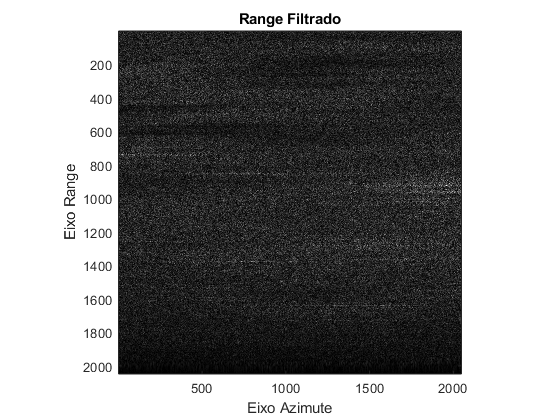

fftlen = 6*N; %Configuração do número de amostras com acréscimos de zeros

data_fft_range = fft(raw_data,fftlen); %Conversão do dado Raw final para domínio da frequência com o tamanho desejado e zeros acrescentados

signal_chirp_fft2 = fft(signal_chirp, fftlen); % Sinal chirp colocado no domínio da frequência

signal_chirp_fft2 = repmat(signal_chirp_fft2,1,N); % Repetição do sinal em colunas 2048

data_fft_range_chirp = data_fft_range .* conj(signal_chirp_fft2); %Convolução dos sinais no domínio da frequência

data_range = ifft(data_fft_range_chirp, fftlen); % Aplicação da Inversa de Fourier para retornar ao domínio do tempo

data_range(N+1:end,:) = []; % Descarte do preenchimento com zeros e criando uma nova matriz

figure
imagesc(abs(data_range))
axis image
colormap('gray')
title('Range Filtrado')
xlabel('Eixo Azimute');
ylabel('Eixo Range');

## *6º Passo:* Gerar sinal em Azimute

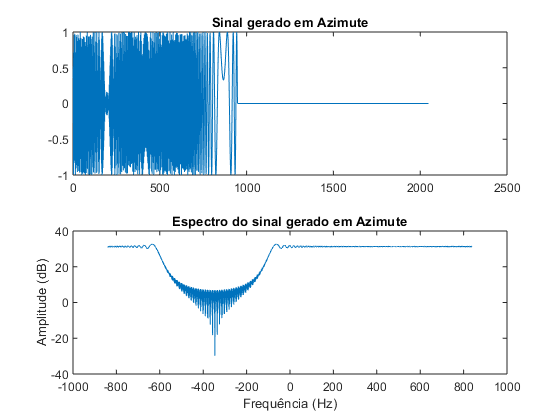

c = 2.9979e+8; % Constante da velocidade da Luz

RGD = (0:N-1)*ts; % Range Gate Delay

R0 = ran_ini + RGD * (c/2); % Equação para calcular o range perpendicular ao azimute

rnc = R0/(1-(lambda*fdc/(2*vel))^2); % Equação Squinted Range

Ka = -2*vel^2./(lambda * rnc); % Taxa FM em azimute

az_beamwidth = rnc * (lambda/lant); % Posição do Squinted Range

tau_az = az_beamwidth / vel; % Largura do pulso azimute

%Função para criar o sinal azimute

for eixoRange = 1:N
    
    slope = Ka(eixoRange);
    tau = tau_az(eixoRange);
    fs = prf;
    
    dt = 1/fs;
    npts = floor(tau*fs);
    t = [-npts/2:npts/2-1]*dt;
    
    chirp_az = [exp(j*2*pi*fdc*t + j*pi*slope*t.^2), zeros(1,N-npts)];
    
    az_ref(eixoRange,:) = chirp_az;
    
end

df = prf/N;
f = (-N/2:N/2-1)*df;

%Plot

figure
subplot(2,1,1)
plot(real(az_ref(1,:)));
title('Sinal gerado em Azimute');
subplot(2,1,2)
plot(f,20*log10(abs(fftshift(fft(az_ref(1,:))))));
title('Espectro do sinal gerado em Azimute');
xlabel('Frequência (Hz)');
ylabel('Amplitude (dB)');

## *7ºPasso:* Aplicação do filtro em Azimute

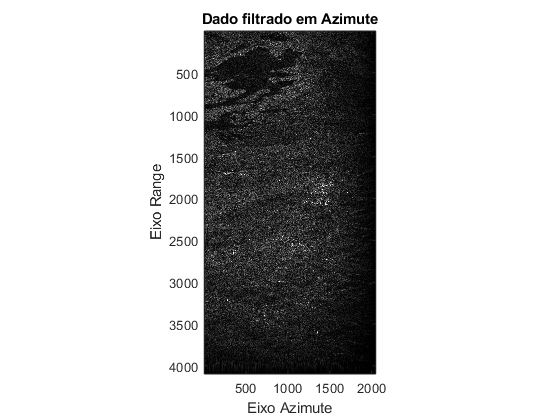

data_fft_azimuth = fft(data_range,fftlen,2); %Aplicando domínio da frequência nos dados range

az_ref_fft = fft(az_ref,fftlen,2); %Sinal azimute no domínio da frequência

data_fft_azimuth_chirp = data_fft_azimuth .* conj(az_ref_fft); %Convolução dos sinais anteriores 

data_azimuth = ifft(data_fft_azimuth_chirp, fftlen,2); % Retornando para o domínio do tempo

data_azimuth(:,N+1:end) = []; %Tirando os zeros da matriz complexa

%Plots
figure(1)
imagesc(abs(repelem(data_azimuth,2,1)),[100,max(abs(data_azimuth(:)))*0.1])
axis image
colormap('gray')
title('Dado filtrado em Azimute')
xlabel('Eixo Azimute');
ylabel('Eixo Range')

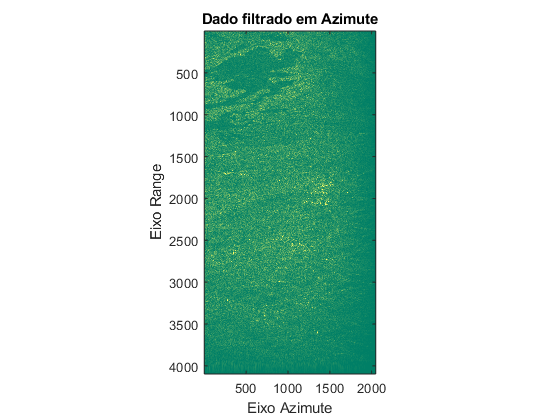


figure(3)
imagesc(abs(repelem(data_azimuth,2,1)),[100,max(abs(data_azimuth(:)))*0.1])
axis image
colormap('summer')
title('Dado filtrado em Azimute')
xlabel('Eixo Azimute');
ylabel('Eixo Range');